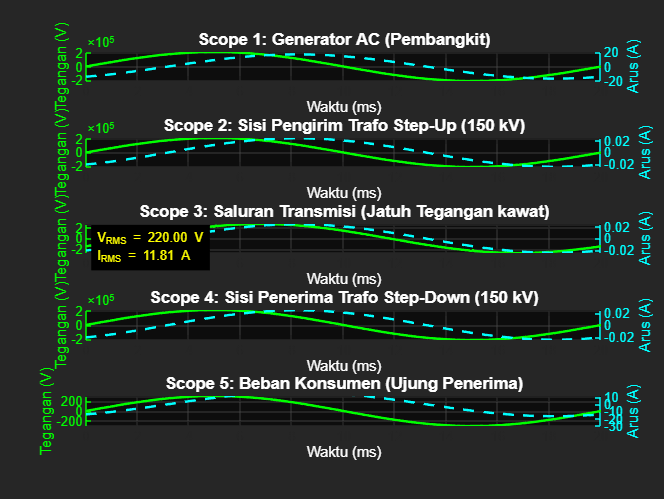

% =========================================================================
% SCRIPT UTAMA: SIMULASI SISTEM TRANSMISI TENAGA LISTRIK MODULAR
% =========================================================================
clear; clc; close all;

% 1. DEKLARASI PARAMETER UTAMA SISTEM (Ubah nilai di sini)
freq = 50;                     % Frekuensi sistem (Hz)
T_period = 1 / freq;            % Durasi satu gelombang penuh (0.02 s)
t = linspace(0, T_period, 500);    % Vektor waktu diskrit (resolusi tinggi)

V_gen_rms = 220;               % Tegangan keluaran generator pembangkit (Volt)
ratio_step_up = 150000 / 220;    % Penaikan tegangan dari 220 V ke 150 kV
R_line = 100;                  % Resistansi kawat transmisi (Ohm)
L_line = 0.15;                 % Induktansi kawat transmisi (Henry)
ratio_step_down = 150000 / 220;  % Penurunan tegangan kembali ke 220 V
R_load = 10;                   % Resistansi beban konsumen RL (Ohm)
L_load = 0.05;                  % Induktansi beban konsumen RL (Henry)

% 2. EKSEKUSI BLOK MODULAR TRANSMISI
v_nominal_load = ac_source(t, V_gen_rms, freq);
i_load = load_system(t, v_nominal_load, R_load, L_load, freq);

[~, i_transmission] = transformer_step_down(v_nominal_load * ratio_step_down, i_load, ratio_step_down);

v_trans_sending_nominal = v_nominal_load * ratio_step_down; 
[v_trans_receiving, v_drop, p_loss] = transmisi_line(t, v_trans_sending_nominal, i_transmission, R_line, L_line);

[v_generator_actual, i_generator] = transformer_step_up(v_trans_sending_nominal / ratio_step_up, i_transmission, ratio_step_up);
v_load_actual = v_trans_receiving / ratio_step_down;

% 3. PERHITUNGAN RMS SECARA NUMERIK (MENGGUNAKAN TRAPZ)
rms_v_gen  = calculate_rms(t, v_generator_actual);
rms_i_gen  = calculate_rms(t, i_generator);
rms_v_send = calculate_rms(t, v_trans_sending_nominal);
rms_v_rec  = calculate_rms(t, v_trans_receiving);
rms_i_line = calculate_rms(t, i_transmission);
rms_v_load = calculate_rms(t, v_load_actual);
rms_i_load = calculate_rms(t, i_load);

% 4. LAPORAN EVALUASI DAYA DAN EFISIENSI
P_gen  = mean(v_generator_actual .* i_generator);
P_loss = mean(p_loss);
P_load = mean(v_load_actual .* i_load);
efisiensi = (P_load / P_gen) * 100;

% 5. PLOT VISUALISASI SCOPE
figure('Name', 'Scope Analisis Sistem Transmisi Jarak Jauh', 'NumberTitle', 'off');
plot_scope(1, t, v_generator_actual, i_generator, rms_v_gen, rms_i_gen, 'Scope 1: Generator AC (Pembangkit)');
plot_scope(2, t, v_trans_sending_nominal, i_transmission, rms_v_send, rms_i_line, 'Scope 2: Sisi Pengirim Trafo Step-Up (150 kV)');
plot_scope(3, t, v_drop, i_transmission, calculate_rms(t, v_drop), rms_i_line, 'Scope 3: Saluran Transmisi (Jatuh Tegangan kawat)');
plot_scope(4, t, v_trans_receiving, i_transmission, rms_v_rec, rms_i_line, 'Scope 4: Sisi Penerima Trafo Step-Down (150 kV)');
plot_scope(5, t, v_load_actual, i_load, rms_v_load, rms_i_load, 'Scope 5: Beban Konsumen (Ujung Penerima)');


% Tampilkan Laporan di Command Window
fprintf('\n=========================================================\n');

fprintf('     LAPORAN ANALISIS TRANSMISI MODULAR JARAK JAUH       \n');

     LAPORAN ANALISIS TRANSMISI MODULAR JARAK JAUH       


fprintf('=========================================================\n');

fprintf('Tegangan Generator AC  : %.2f V_rms\n', rms_v_gen);

Tegangan Generator AC  : 150000.00 V_rms


fprintf('Daya yang Dibangkitkan : %.2f Watt (Rata-rata)\n', P_gen);

Daya yang Dibangkitkan : 949818.01 Watt (Rata-rata)


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf('Tegangan Kirim Transmisi: %.2f kV_rms\n', rms_v_send/1000);

Tegangan Kirim Transmisi: 150.00 kV_rms


fprintf('Tegangan Terima Transmisi: %.2f kV_rms\n', rms_v_rec/1000);

Tegangan Terima Transmisi: 150.00 kV_rms


fprintf('Rugi-Rugi Daya Kawat   : %.2f Watt\n', P_loss);

Rugi-Rugi Daya Kawat   : 0.03 Watt


fprintf('---------------------------------------------------------\n');

---------------------------------------------------------


fprintf('Tegangan Beban Konsumen: %.2f V_rms\n', rms_v_load);

Tegangan Beban Konsumen: 220.00 V_rms


fprintf('Daya yang Diterima Beban: %.2f Watt (Rata-rata)\n', P_load);

Daya yang Diterima Beban: 1393.04 Watt (Rata-rata)


fprintf('EFISIENSI TRANSMISI    : %.2f %%\n', efisiensi);

EFISIENSI TRANSMISI    : 0.15 %


fprintf('=========================================================\n');